clear;
load Sensor_data_selected.mat;
groupTest=[5,11,17];
groupTrain=[1:4,6:10,12:16,18];
for i=1:size(groupTrain,2)
    XTrain{i,1}=inputs{groupTrain(i)};
    YTrain{i,1}=outputs{groupTrain(i)};
end
% mu = mean([XTrain{:}],2);
% sig = std([XTrain{:}],0,2);
% 
% for i = 1:numel(XTrain)
%     XTrain{i} = (XTrain{i} - mu) ./ sig;
% end

X=[];
Y=[];
for i = 1:numel(inputs)
    X=[X;inputs{i}'];
    Y=[Y;outputs{i}'];
end
%[gam,sig2] = PSO_LSSVM(X,Y)

Start Plotting...

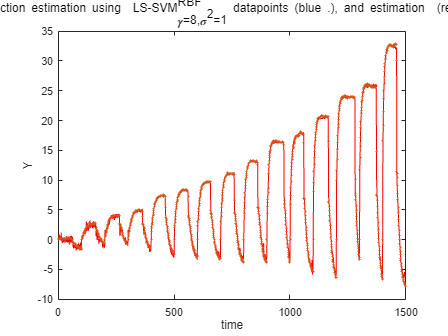

finished


gam=8;
sig2=1;
X=[];
Y=[];
for i = 1:numel(XTrain)
    X=[X;XTrain{i}'];
    Y=[Y;YTrain{i}'];
end
type = 'f';
%% 模型训练和图形化显示 
[alpha,b] = trainlssvm({X,Y,type,gam,sig2,'RBF_kernel','preprocess'});
plotlssvm({X,Y,type,gam,sig2,'RBF_kernel','preprocess'},{alpha,b});

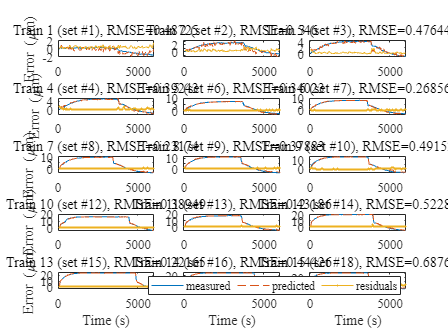

YTrain_Pred=cell(numel(XTrain),1);
for i = 1:numel(XTrain)
   YTrain_Pred{i}=simlssvm({X,Y,type,gam,sig2,'RBF_kernel','preprocess'},{alpha,b},XTrain{i}')';
end

rmses=zeros(numel(XTrain),1);
for i = 1:numel(XTrain)
    rmses(i) = sqrt(mean(mean((YTrain_Pred{i}-YTrain{i}).^2)));
end
t=60:60:6000;
figure
for i = 1:numel(YTrain_Pred)
    subplot(5,3,i)
    
    plot(t,YTrain{i})
    hold on
    plot(t,YTrain_Pred{i},'--')
    plot(t,abs(YTrain_Pred{i}-YTrain{i}),'.-')
    hold off
    
    %ylim([0 thr + 25])
    title("Train "+i+" (set #" + groupTrain(i)+"), RMSE="+rmses(i));
    if mod(i,3)==1
        ylabel("Error (\mum)");
    end
    if i>12
        xlabel("Time (s)");
    end
    set(gca,'fontsize',12,'fontname','times new roman');
end
legend({'measured','predicted','residuals'},'NumColumns',3);
set(gca,'fontsize',12,'fontname','times new roman');

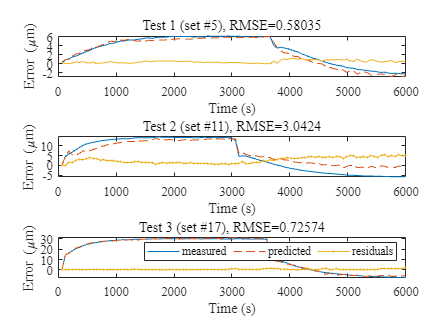

%测试输出
for i=1:size(groupTest,2)
    XTest{i,1}=inputs{groupTest(i)};
    YTest{i,1}=outputs{groupTest(i)};
end
YTest_Pred=cell(numel(XTest),1);

for i = 1:numel(XTest)
%    XTest{i} = (XTest{i} - mu) ./ sig;
   YTest_Pred{i}=simlssvm({X,Y,type,gam,sig2,'RBF_kernel','preprocess'},{alpha,b},XTest{i}')';
end
rmses=zeros(numel(XTest),1);
for i = 1:numel(YTest)
    rmses(i) = sqrt(mean(mean((YTest_Pred{i}-YTest{i}).^2)));
end
t=60:60:6000;
figure

for i = 1:numel(YTest_Pred)
    subplot(3,1,i)
    
    plot(t,YTest{i})
    hold on
    plot(t,YTest_Pred{i},'--')
    plot(t,abs(YTest_Pred{i}-YTest{i}),'.-')
    hold off
    
    %ylim([0 thr + 25])
    title("Test "+i+" (set #" + groupTest(i)+"), RMSE="+rmses(i));
    xlabel("Time (s)");
    ylabel("Error (\mum)");
    set(gca,'fontsize',12,'fontname','times new roman');
end
legend({'measured','predicted','residuals'},'NumColumns',3);
set(gca,'fontsize',12,'fontname','times new roman');